# Forward testing of differentiation matrices

*Note: You will only be able to run this once you have written the functions bulid_grid() and build_ops()!*

The discrete operators `D` and `G` are differentiation matrices. If `f` is a vector that is the discrete representation of a function $f\left(x\right)$, then `G*f` returns a discrete approximation of the derivative $\frac{\partial f}{\partial x}$. 

For the one-dimensional examples below the discrete operators can be generated as follows:

clear, clc
set_demo_defaults
Grid.xmin = 0; Grid.xmax = 3; Grid.Nx = 10;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid); L = D*G;

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =    -3.3333    3.3333         0         0         0         0         0         0         0         0         0
         0   -3.3333    3.3333         0         0         0         0         0         0         0         0
         0         0   -3.3333    3.3333         0         0         0         0         0         0         0
         0         0         0   -3.3333    3.3333         0         0         0         0         0         0
         0         0         0         0   -3.3333    3.3333         0         0         0         0         0
         0         0         0         0         0   -3.3333    3.3333         0         0         0         0
         0         0         0         0         0         0   -3.3333    3.3333         0         0         0
         0         0         0         0         0         0         0   -3.3333    3.3333         0         0
         0         0         0         0         0         0         0         0   -3.3333    3.3333      

ans =          0         0         0         0         0         0         0         0         0         0
   -3.3333    3.3333         0         0         0         0         0         0         0         0
         0   -3.3333    3.3333         0         0         0         0         0         0         0
         0         0   -3.3333    3.3333         0         0         0         0         0         0
         0         0         0   -3.3333    3.3333         0         0         0         0         0
         0         0         0         0   -3.3333    3.3333         0         0         0         0
         0         0         0         0         0   -3.3333    3.3333         0         0         0
         0         0         0         0         0         0   -3.3333    3.3333         0         0
         0         0         0         0         0         0         0   -3.3333    3.3333         0
         0         0         0         0         0         0         0         0   -3

ans =      1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     1


ans =     0.5000         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0
         0         0    0.5000    0.5000         0         0         0         0         0         0
         0         0         0    0.5000    0.5000         0         0         0         0         0
         0         0         0         0    0.5000    0.5000         0         0         0         0
         0         0         0         0         0    0.5000    0.5000         0         0         0
         0         0         0         0         0         0    0.5000    0.5000         0         0
         0         0         0         0         0         0         0    0.5000    0.5000         0
         0         0         0         0         0         0         0         0    0

ans =     1.0000         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0
         0         0    0.5000    0.5000         0         0         0         0         0         0
         0         0         0    0.5000    0.5000         0         0         0         0         0
         0         0         0         0    0.5000    0.5000         0         0         0         0
         0         0         0         0         0    0.5000    0.5000         0         0         0
         0         0         0         0         0         0    0.5000    0.5000         0         0
         0         0         0         0         0         0         0    0.5000    0.5000         0
         0         0         0         0         0         0         0         0    0

Here `Grid` is a structure that contains all information about the grid and `build_grid()` is a function that generates all the necessary information. The function `build_ops()` then generates the discrete operators for the grid. The matrix `L` corresponds to the Laplacian operator and hence to a decond derivative matrix in 1D.

The othe matrices returned by `build_ops()` are:

`C` = discrete curl (does not exist in 1D)

`I` = identity

`M` = mean matrix - computes arithmetic mean of cell centered values on the cell faces

## Visualizing the fill pattern of the operators

We can viualize the sparity pattern of our matrices with the [spy()](https://www.mathworks.com/help/matlab/ref/spy.html) function.

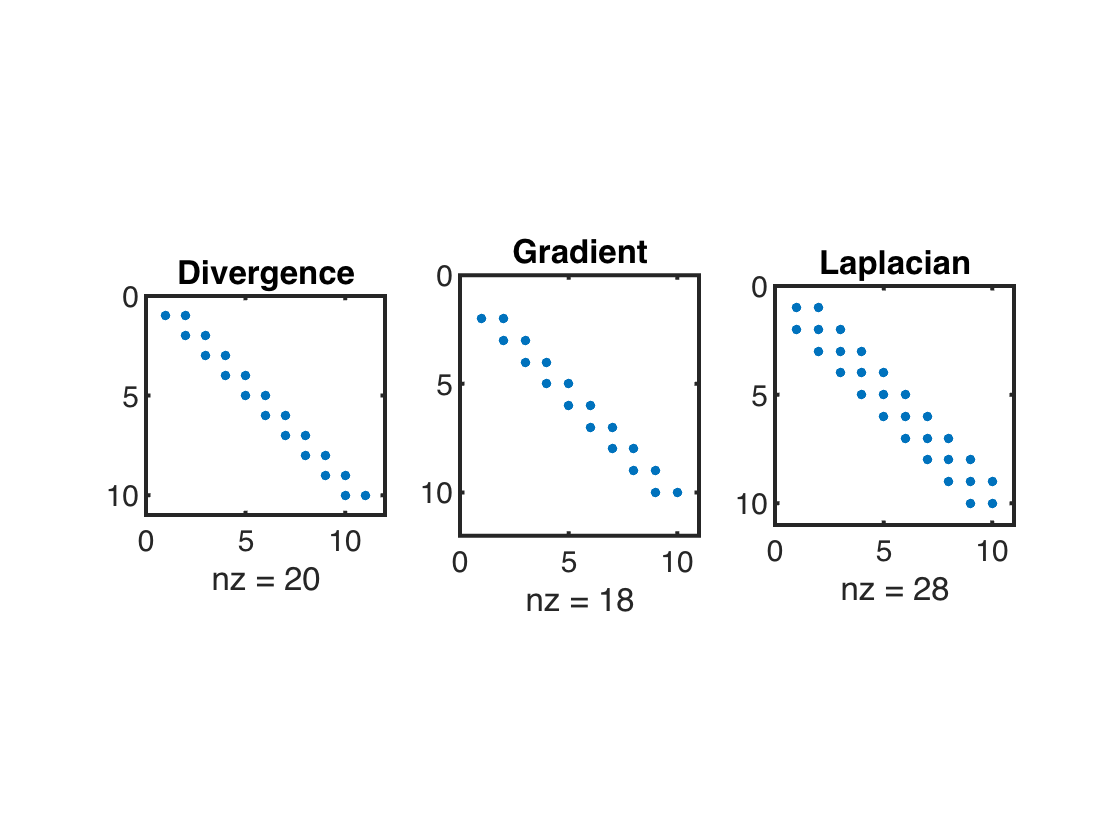

figure(1)
subplot 131
spy(D)
title 'Divergence'

subplot 132
spy(G)
title 'Gradient'

subplot 133
spy(L)
title 'Laplacian'

Not the Laplacian has the standard tri-diagonal structure expected for the 1D discretization of the second derivative.

## Testing the discrete operators

We would like to setablish that our discrete operators are correct, before moving on in our implementation. The obvious idea is to solve a particular boundary value problem (BVP) with a known analytic solution and to compare it with the numerical solution. However, this is not the optimal testing strategy, because the full numerical solution of a boundary value problem (BVP) requires both the discrete operators and the implementation of the boundary conditions. The BVP solution may be wrong, even is the diecrete operatores are correct, becuse the error might be in the implementation of boundary condition.

To test only the correctness of the discrete operators, we can use the knowledge that they simply differentiate a function. The only caveat is that the derivative is **not** evaluated at a the same location, due to the staggered grid!

To test the operators we need a finer grid.

Grid.xmin = 0; Grid.xmax = 3; Grid.Nx = 30;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid); L = D*G;

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =    -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   -10    10     0     0     

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   -10    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   -10    10     0     0     0     0     0     0     0     0     

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.5000    0.5000         0         0         0         0         0 

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.5000    0.5000         0         0         0         0         0 

## Differentiating a function that statisfies the natural BC's

Consider the function $f(x) = e^{\cos(2\pi x)}$ on the domain $x \in \left[0,\,3\right]$, which statifies the natural boundary conditions, i.e., $\mbox{d}f/\mbox{d}x = 0$ at the boundaries. These are the boundary conditions that are build into the discrete gradient `G`. 

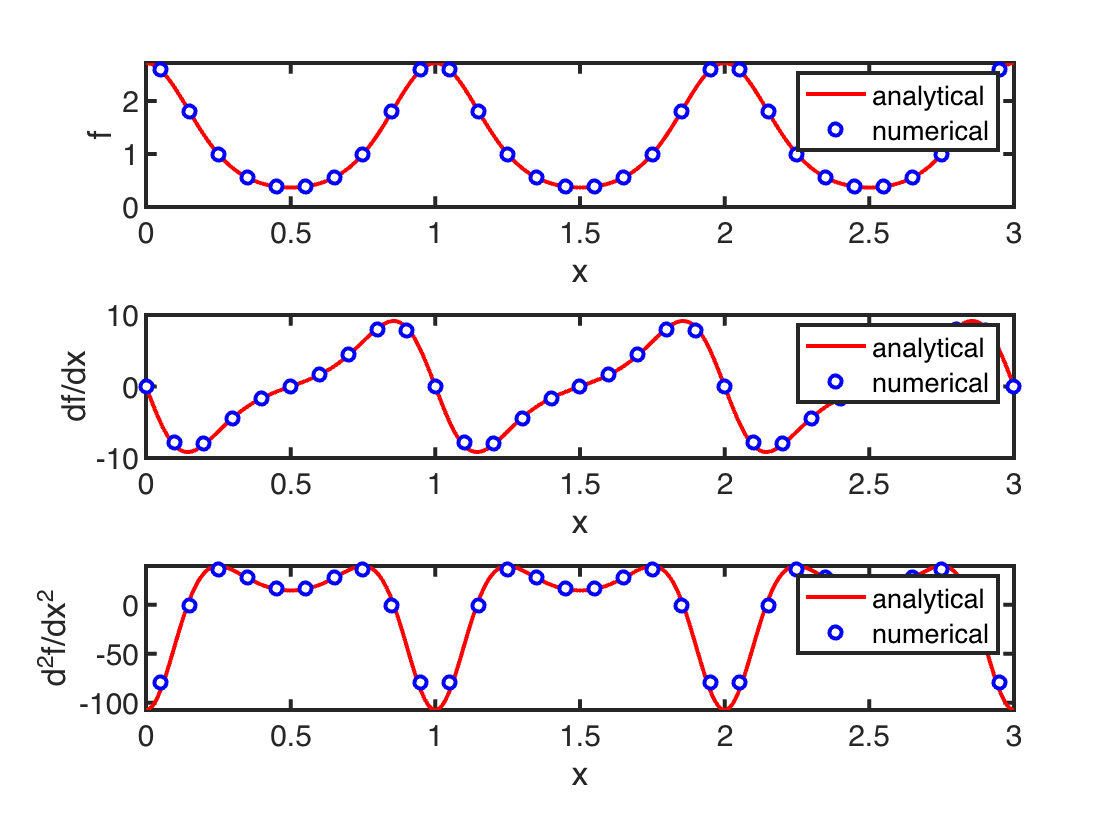

xa = linspace(Grid.xmin,Grid.xmax,3e2);
f = @(x) exp(cos(2*pi*x));
dfdx = @(x) -exp(cos(2*pi*x)).*sin(2*pi*x)*2*pi; 
d2fdx2 = @(x) -2*pi^2*exp(cos(2*pi*x)).*(2*cos(2*pi*x)+cos(4*pi*x)-1);

figure(2)
subplot 311
plot(xa,f(xa),'r',Grid.xc,f(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'f'
legend('analytical','numerical')

subplot 312
plot(xa,dfdx(xa),'r',Grid.xf,G*f(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'df/dx'
legend('analytical','numerical')

subplot 313
plot(xa,d2fdx2(xa),'r',Grid.xc,L*f(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'd^2f/dx^2'
legend('analytical','numerical')

The figure shows that discrete derivatives approximat the analytic derivatives well. Note that the two derivatives are evaluated at different locations: 

- First derivative is evaluated at cell faces.

- Second derivative is evaluated at cell centers.

## Differentiation a function that does NOT satisfy the natural BC's

Consider the function $g(x) = e^{\cos(2\pi x)}$, which does not satify the natural boundary conditions, i.e., the homogeneous Neumann boundary conditions of the discrete gradient operator `G`.

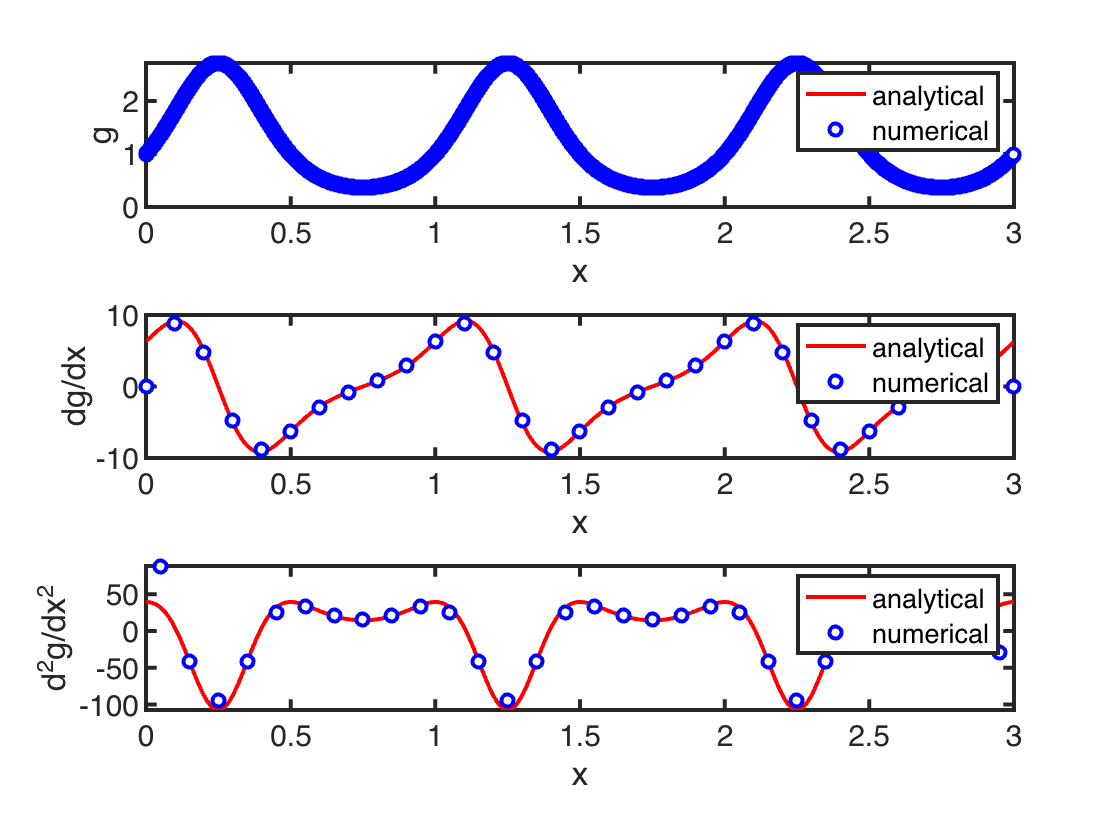

g = @(x) exp(sin(2*pi*x));
dgdx = @(x) exp(sin(2*pi*x)).*cos(2*pi*x)*2*pi; 
d2gdx2 = @(x) 2*pi^2*exp(sin(2*pi*x)).*(-2*sin(2*pi*x)+cos(4*pi*x)+1);

figure(3)
subplot 311
plot(xa,g(xa),'r',Grid.xc,g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'g'
legend('analytical','numerical')

subplot 312

plot(xa,dgdx(xa),'r',Grid.xf,G*g(Grid.xc),'bo','markerfacecolor','w','markersize',6)

Unrecognized function or variable 'G'.

xlabel 'x'
ylabel 'dg/dx'
legend('analytical','numerical')

subplot 313
plot(xa,d2gdx2(xa),'r',Grid.xc,L*g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'd^2g/dx^2'
legend('analytical','numerical')

The figure shows that the derivatives are still well approximated in the interior of the domain. The error on the boundaries is large and does not reduce with increasing refinement of the grid. We will see later that the implementation of the boundary condition takes care of this problem.

## Convergence with refinement

To check the convergence of the discrete operators compute the error between $\partial f/\partial x$ and `G*f` and $\partial^2 f/\partial x^2$ and `D*G*f` as the number grid points increases. 

Nx = round(logspace(1,6,10));
error_grad = zeros(size(Nx)); error_lap = zeros(size(Nx));

for i = 1:length(Nx)
    Grid.Nx = Nx(i); Grid = build_grid(Grid);
    clear D G I
    pause(1e-3)
    tic;
    [D,G,C,I,M] = build_ops(Grid); 
    time(i) = toc;
    L = D*G;
    error_grad(i) = norm(dfdx(Grid.xf)-G*f(Grid.xc))/norm(dfdx(Grid.xf));
    error_lap(i) = norm(d2fdx2(Grid.xc)-D*G*f(Grid.xc))/norm(d2fdx2(Grid.xc));
end

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =    -3.3333    3.3333         0         0         0         0         0         0         0         0         0
         0   -3.3333    3.3333         0         0         0         0         0         0         0         0
         0         0   -3.3333    3.3333         0         0         0         0         0         0         0
         0         0         0   -3.3333    3.3333         0         0         0         0         0         0
         0         0         0         0   -3.3333    3.3333         0         0         0         0         0
         0         0         0         0         0   -3.3333    3.3333         0         0         0         0
         0         0         0         0         0         0   -3.3333    3.3333         0         0         0
         0         0         0         0         0         0         0   -3.3333    3.3333         0         0
         0         0         0         0         0         0         0         0   -3.3333    3.3333      

ans =          0         0         0         0         0         0         0         0         0         0
   -3.3333    3.3333         0         0         0         0         0         0         0         0
         0   -3.3333    3.3333         0         0         0         0         0         0         0
         0         0   -3.3333    3.3333         0         0         0         0         0         0
         0         0         0   -3.3333    3.3333         0         0         0         0         0
         0         0         0         0   -3.3333    3.3333         0         0         0         0
         0         0         0         0         0   -3.3333    3.3333         0         0         0
         0         0         0         0         0         0   -3.3333    3.3333         0         0
         0         0         0         0         0         0         0   -3.3333    3.3333         0
         0         0         0         0         0         0         0         0   -3

ans =      1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     1


ans =     0.5000         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0
         0         0    0.5000    0.5000         0         0         0         0         0         0
         0         0         0    0.5000    0.5000         0         0         0         0         0
         0         0         0         0    0.5000    0.5000         0         0         0         0
         0         0         0         0         0    0.5000    0.5000         0         0         0
         0         0         0         0         0         0    0.5000    0.5000         0         0
         0         0         0         0         0         0         0    0.5000    0.5000         0
         0         0         0         0         0         0         0         0    0

ans =     1.0000         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0
         0         0    0.5000    0.5000         0         0         0         0         0         0
         0         0         0    0.5000    0.5000         0         0         0         0         0
         0         0         0         0    0.5000    0.5000         0         0         0         0
         0         0         0         0         0    0.5000    0.5000         0         0         0
         0         0         0         0         0         0    0.5000    0.5000         0         0
         0         0         0         0         0         0         0    0.5000    0.5000         0
         0         0         0         0         0         0         0         0    0

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =    -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   -12    12     0     0     0     0     0     0     0     0     0     0     0

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   -12    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =    -43    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   -43    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   -43    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   -43    43     0     0     0     0     0     0     0     0     0     0 

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   -43    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   -43    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   -43    43     0     0     0     0     0     0     0     0     0     0     0 

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =  -154.6667  154.6667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0 -154.6667  154.6667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
 -154.6667  154.6667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans =   -556   556     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0  -556   556     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0  -556   556     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0  -556   556     0     0     0     0     0     0     0     0     0     0 

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
  -556   556     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0  -556   556     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0  -556   556     0     0     0     0     0     0     0     0     0     0     0 

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans = 	1.0e+03 *

   -1.9983    1.9983         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -1.9983    1.9983         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

ans = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.9983    1.9983         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ans = 	1.0e+03 *

   -7.1813    7.1813         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -7.1813    7.1813         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

ans = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -7.1813    7.1813         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

ans =     0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

B1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Error using full
Requested 77426x77427 (44.7GB) array exceeds maximum array size preference (8.0GB). This might cause MATLAB to become unresponsive.

Error in build_ops (line 29)
full(D)

Related documentation


figure(4)
clf
subplot 121
loglog(Nx,error_grad,'ro','markerfacecolor','w'), hold on
loglog(Nx,error_lap,'bo','markerfacecolor','w')
semilogy(Nx,Nx.^(-2)*1e2,'k--')
xlabel 'Nx', ylabel 'error'
xlim([Nx(1)-1e-3 Nx(end)+1e-3])
legend('gradient','Laplacian')
pbaspect([1 .8 1])
subplot 122
loglog(Nx,time,'bo','markerfacecolor','w'), hold on
semilogy(Nx,min(time)*Nx/100,'k--')
xlabel 'Nx', ylabel 'time [s]'
pbaspect([1 .8 1])

The graph on the left shows the decline of the numerical error as a function of increasing grid refinement. The dashed line indicates the quadratic slope expected for that is expected for the central difference, which is second order accurate. Note, as the grid gets very fine (N > 500,000) the numerical rounding error takes over.

The graph on the right shows the time required to compute the discrete operators as the grid size increases with a dashed line indicating linear increase. The discrete opertors can be assemble very efficiently using the [spdiags()](https://www.mathworks.com/help/matlab/ref/spdiags.html) function.

## Auxillary functions

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

